# Fault Detection and Localization in Single-Phase Power Transmission Using Deep Signal Anomaly Detector in Simulink

clear all;
clc;

## Modeling Single-phase power transmission system

Open and examine the Simulink model `PowerTransmissionModel` which is designed to model the power transmission system.

we converted the original Model in the example from three phase into single phase,  To do this, we modified the PowerTransmissionModel as the following: 

we replaced the following from three phase into single phase: 

1- AC source . 

2- voltage and current sensors  

3- Two-Winding Transformer (Three-Phase) into Tap-Changing  transformer 

4- Transmission lines (Three-Phase)  into Transmission lines (single-Phase)  

5-Wye Connected Load into normal Load connected.

Finally we added A faults on each line to be as Short Circuit that enabled separately.

powersysModel = "PowerTransmissionModel.slx";
open_system(powersysModel);

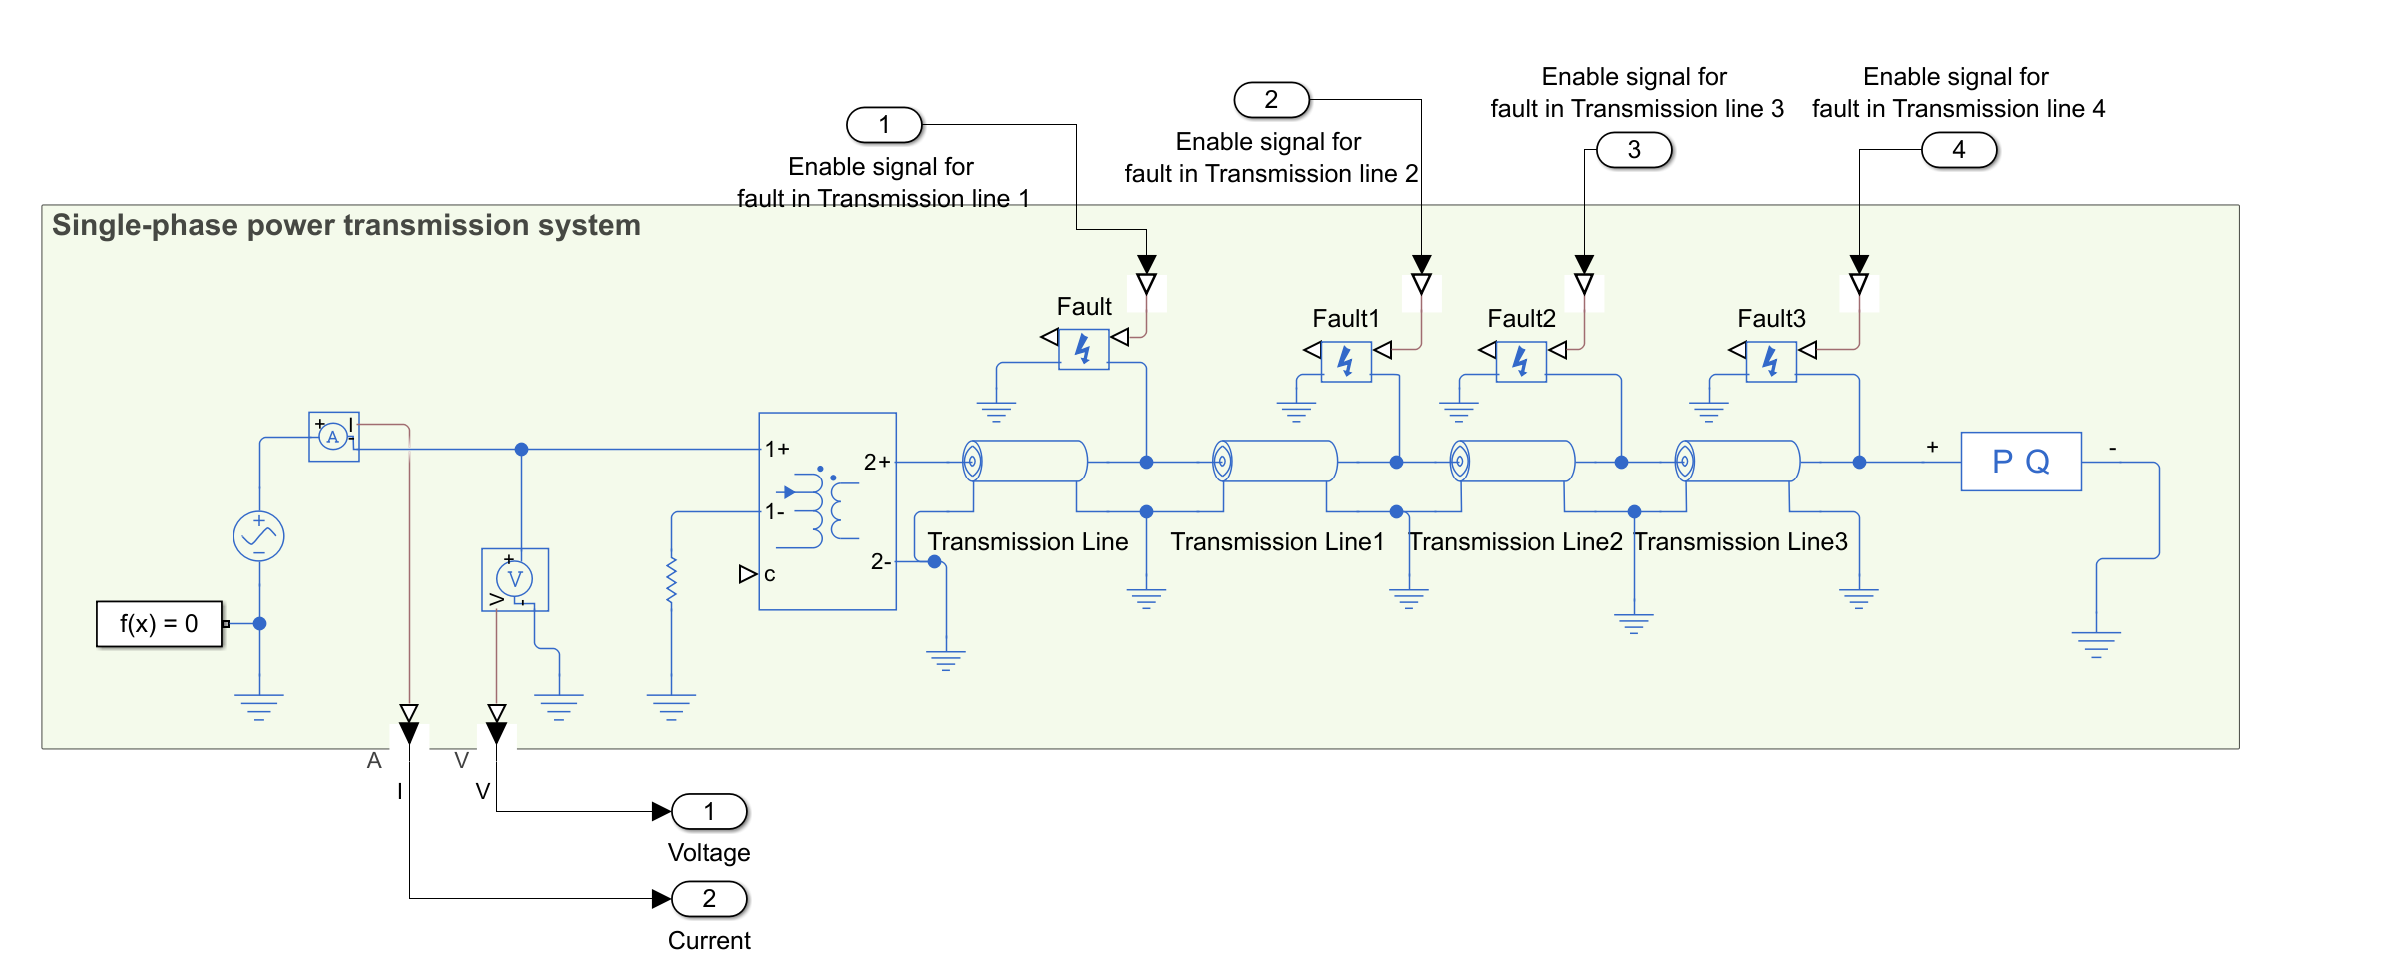

## Generate training data

Open the Simulink model `TrainingModel`. Use this model to generate the training data for the autoencoder.

close_system(powersysModel,0);
trainModel = "TrainingModel.slx";
open_system(trainModel);

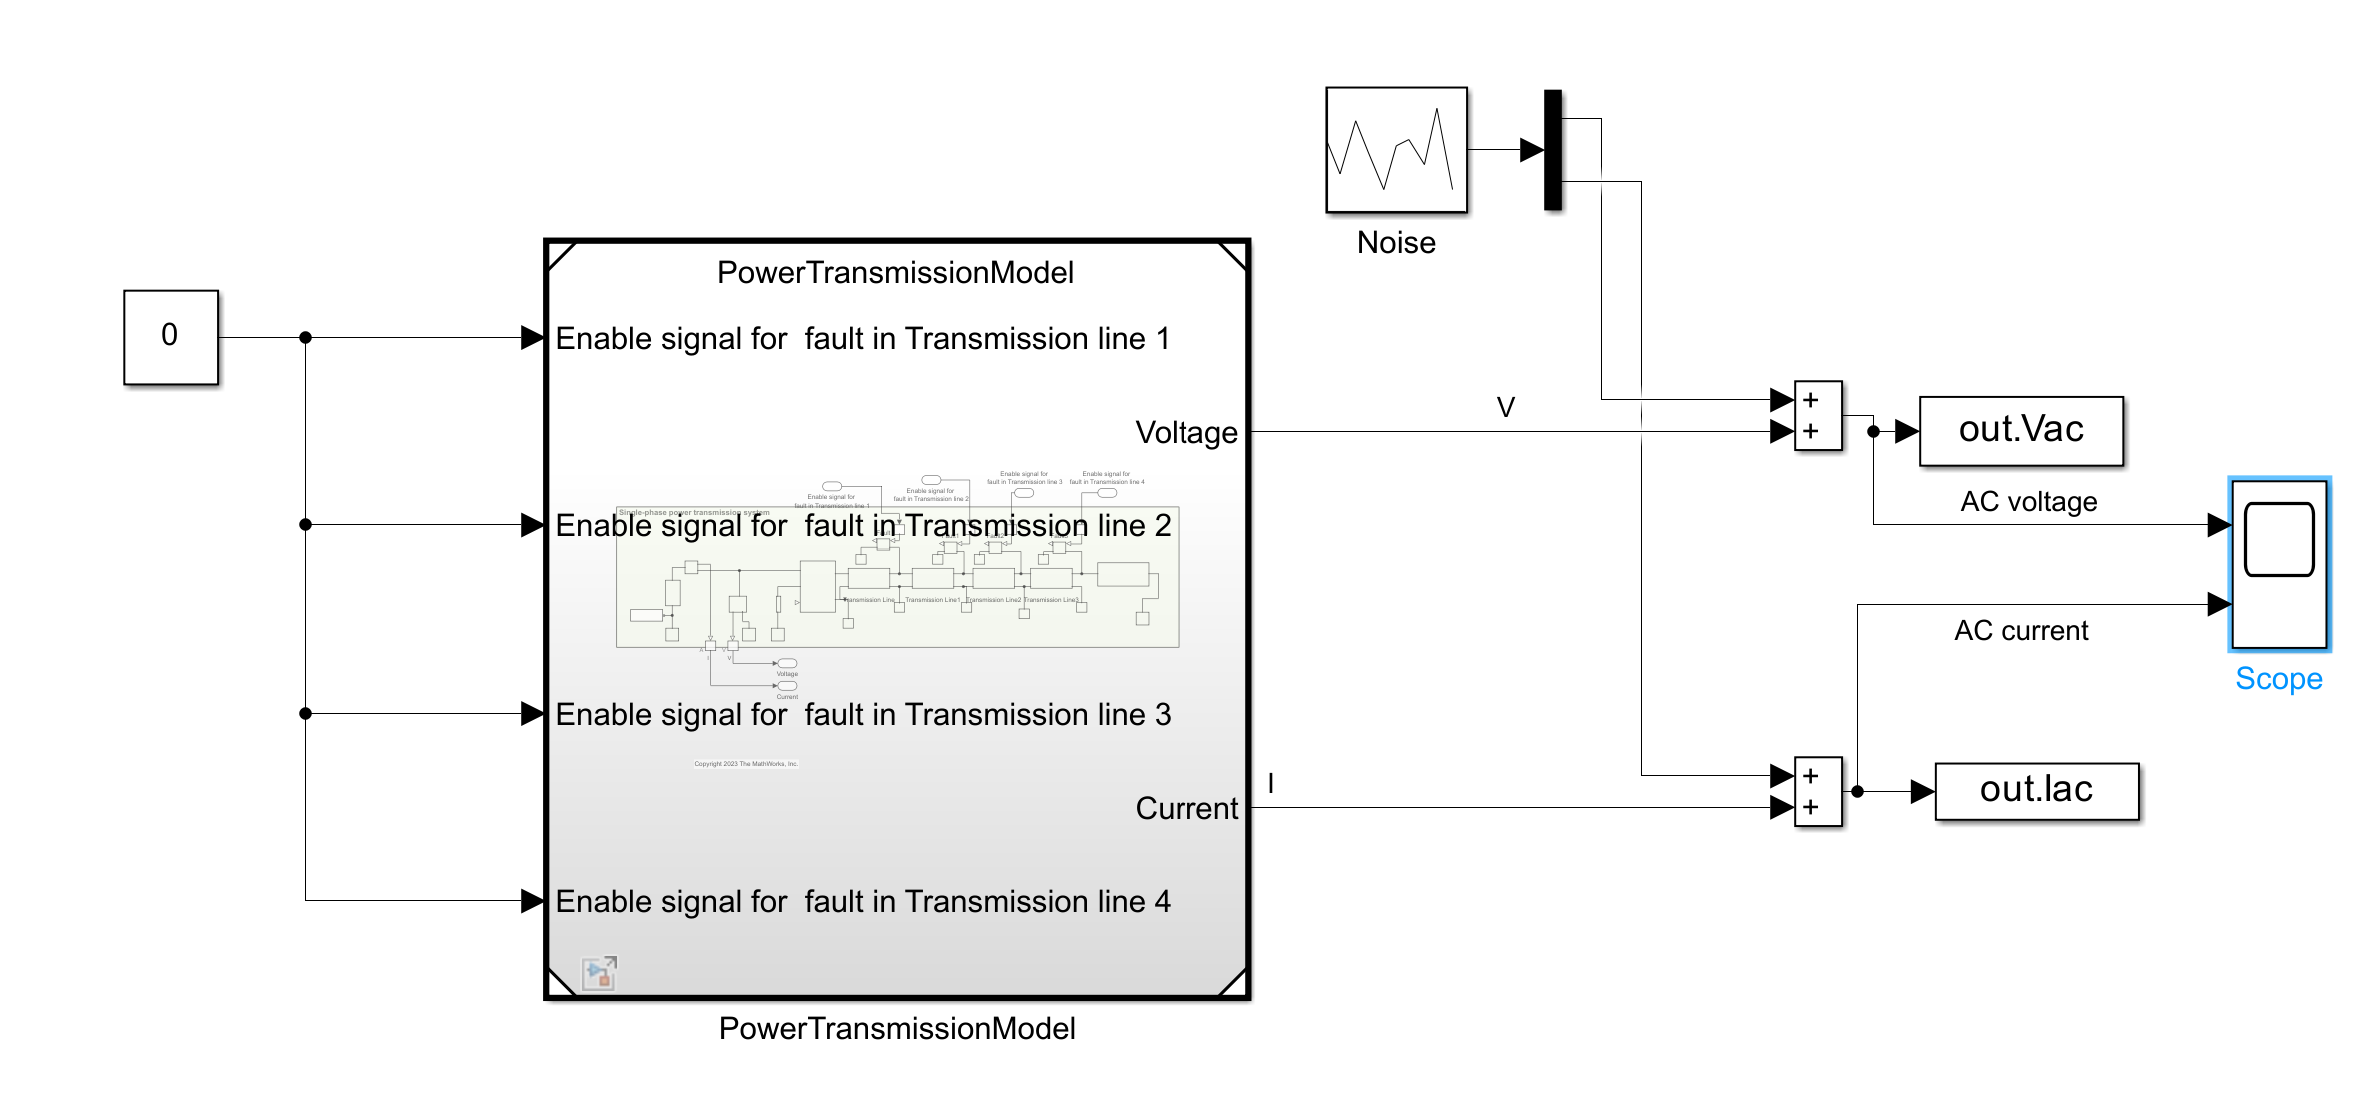

Simulate the model to generate the training data.

out = sim(trainModel);
close_system(trainModel,0);

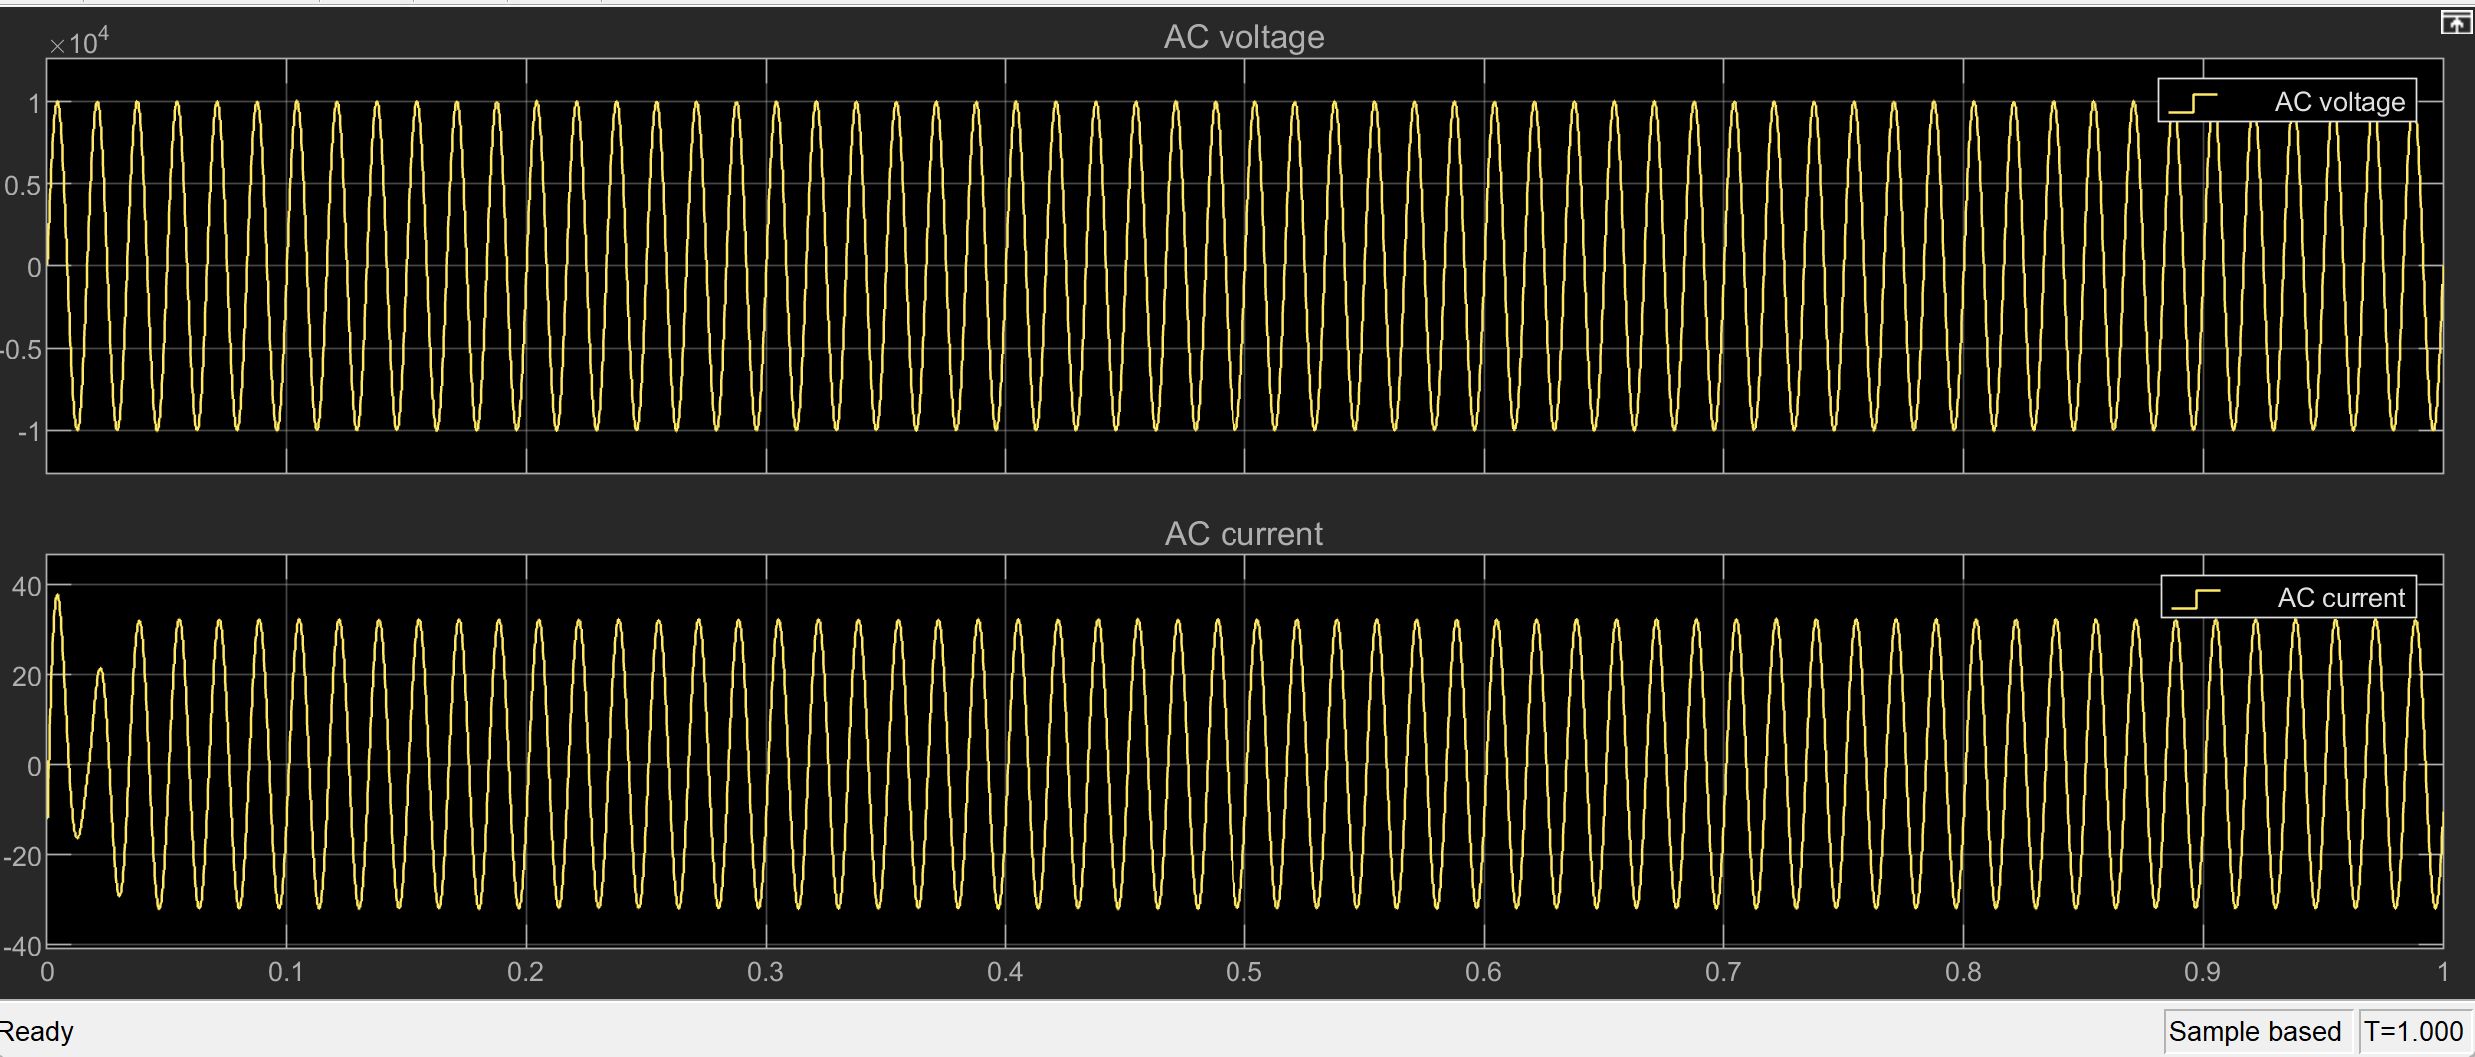

The single-phase currents and voltages are used as input features to train the network. Since the ranges of voltages and currents can be different, normalize their values using the respective values of standard deviation.

Vac = out.Vac; 
Iac = out.Iac;

stdV = std(Vac(:));
stdI = std(Iac(:));

% Normalize voltages and currents
Vac = Vac/stdV;
Iac = Iac/stdI;

% Combine normalized voltage and currents
VInorm = [Vac Iac];


## Part 1: Detect fault in three-phase transmission line

This section shows how to detect the occurrence of a fault in three-phase power line, without explicitly identifying the specific lines in which the fault occurs.

### Create and train the LSTM autoencoder

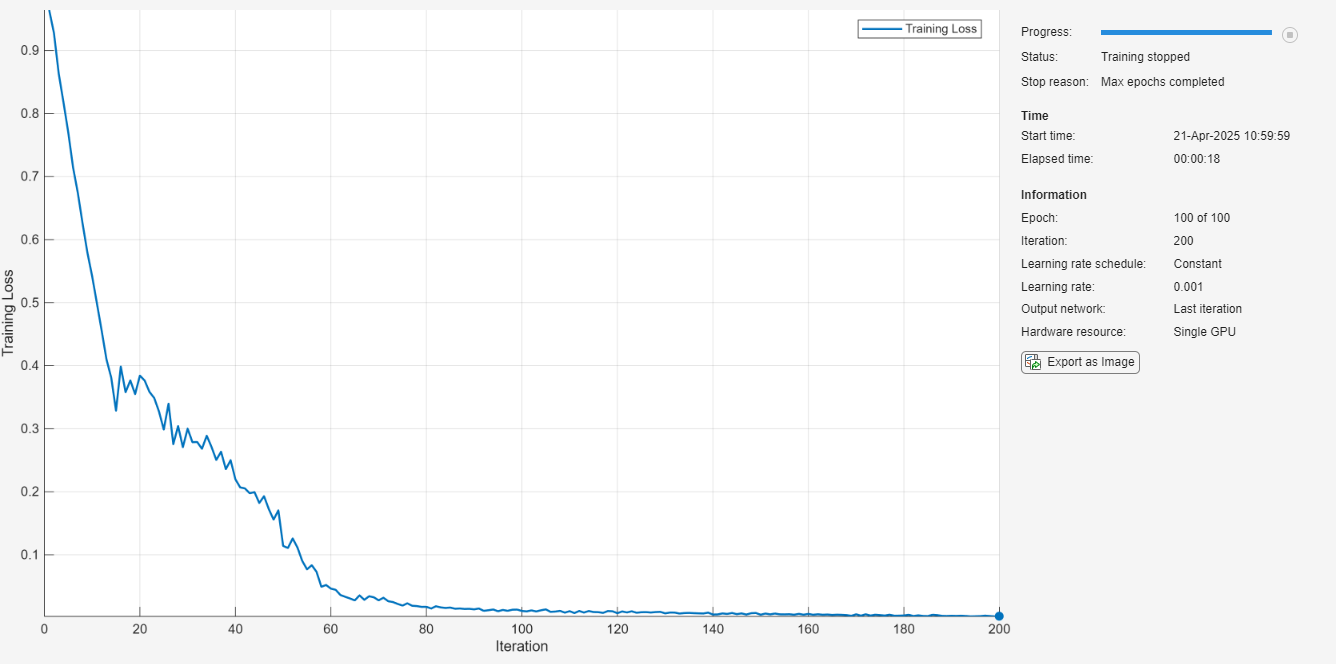

detector = deepSignalAnomalyDetector(2, "lstm", ...
    EncoderHiddenUnits=32, ...
    DecoderHiddenUnits=32, ...
    WindowLength=50, ...
    ThresholdMethod="max", ...
    ThresholdParameter=2);

sequenceLength = 64;

options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    MiniBatchSize=64, ...
    GradientThreshold=1, ...
    SequenceLength=64, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);


% Train the detector
trainNow = true;
if trainNow
    trainDetector(detector,VInorm,options);
end

Save the trained network and detection parameters of the trained detector to a MAT-file.

if trainNow
   saveModel(detector, "singlePhaseFaultDetector.mat");
end

### Fault detection in Simulink

Open and examine the Simulink model `FaultDetectionModel`. This model simulates a three-phase power transmission system with short-circuit faults and detects these faults using the Deep Signal Anomaly Detector block by making use of the MAT-file generated in the previous step.

detectionModel = "FaultDetectionModel";
open_system(detectionModel);

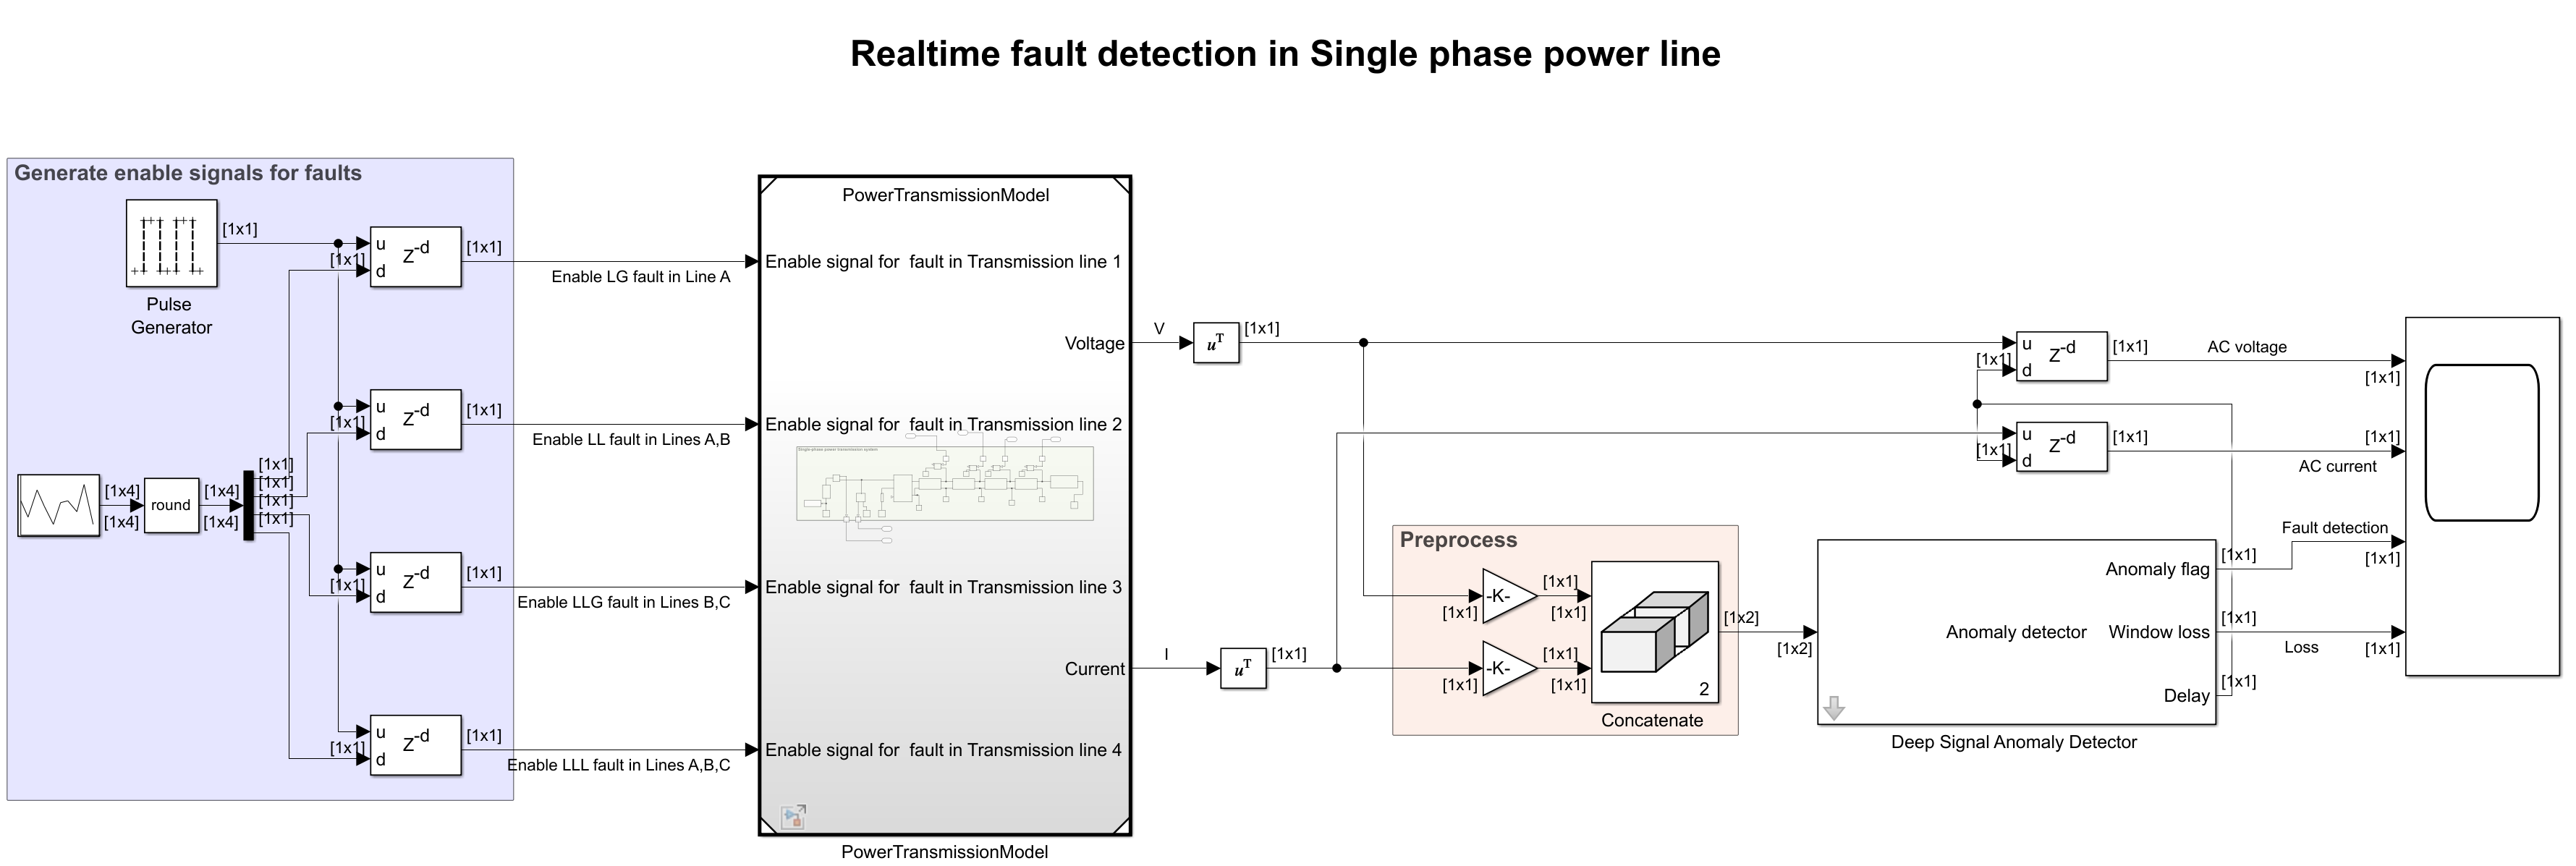

#### Fault generation

Similar to the training model, this model utilizes `PowerTransmissionModel` as a Model Reference. 

#### Anomaly detection

Simulate the model.

sim(detectionModel);

On the [Time Scope,](docid:dsp_ref#f5-1117037) you can see the delayed Single-phase voltage and current signals, fault detection and estimated loss. 

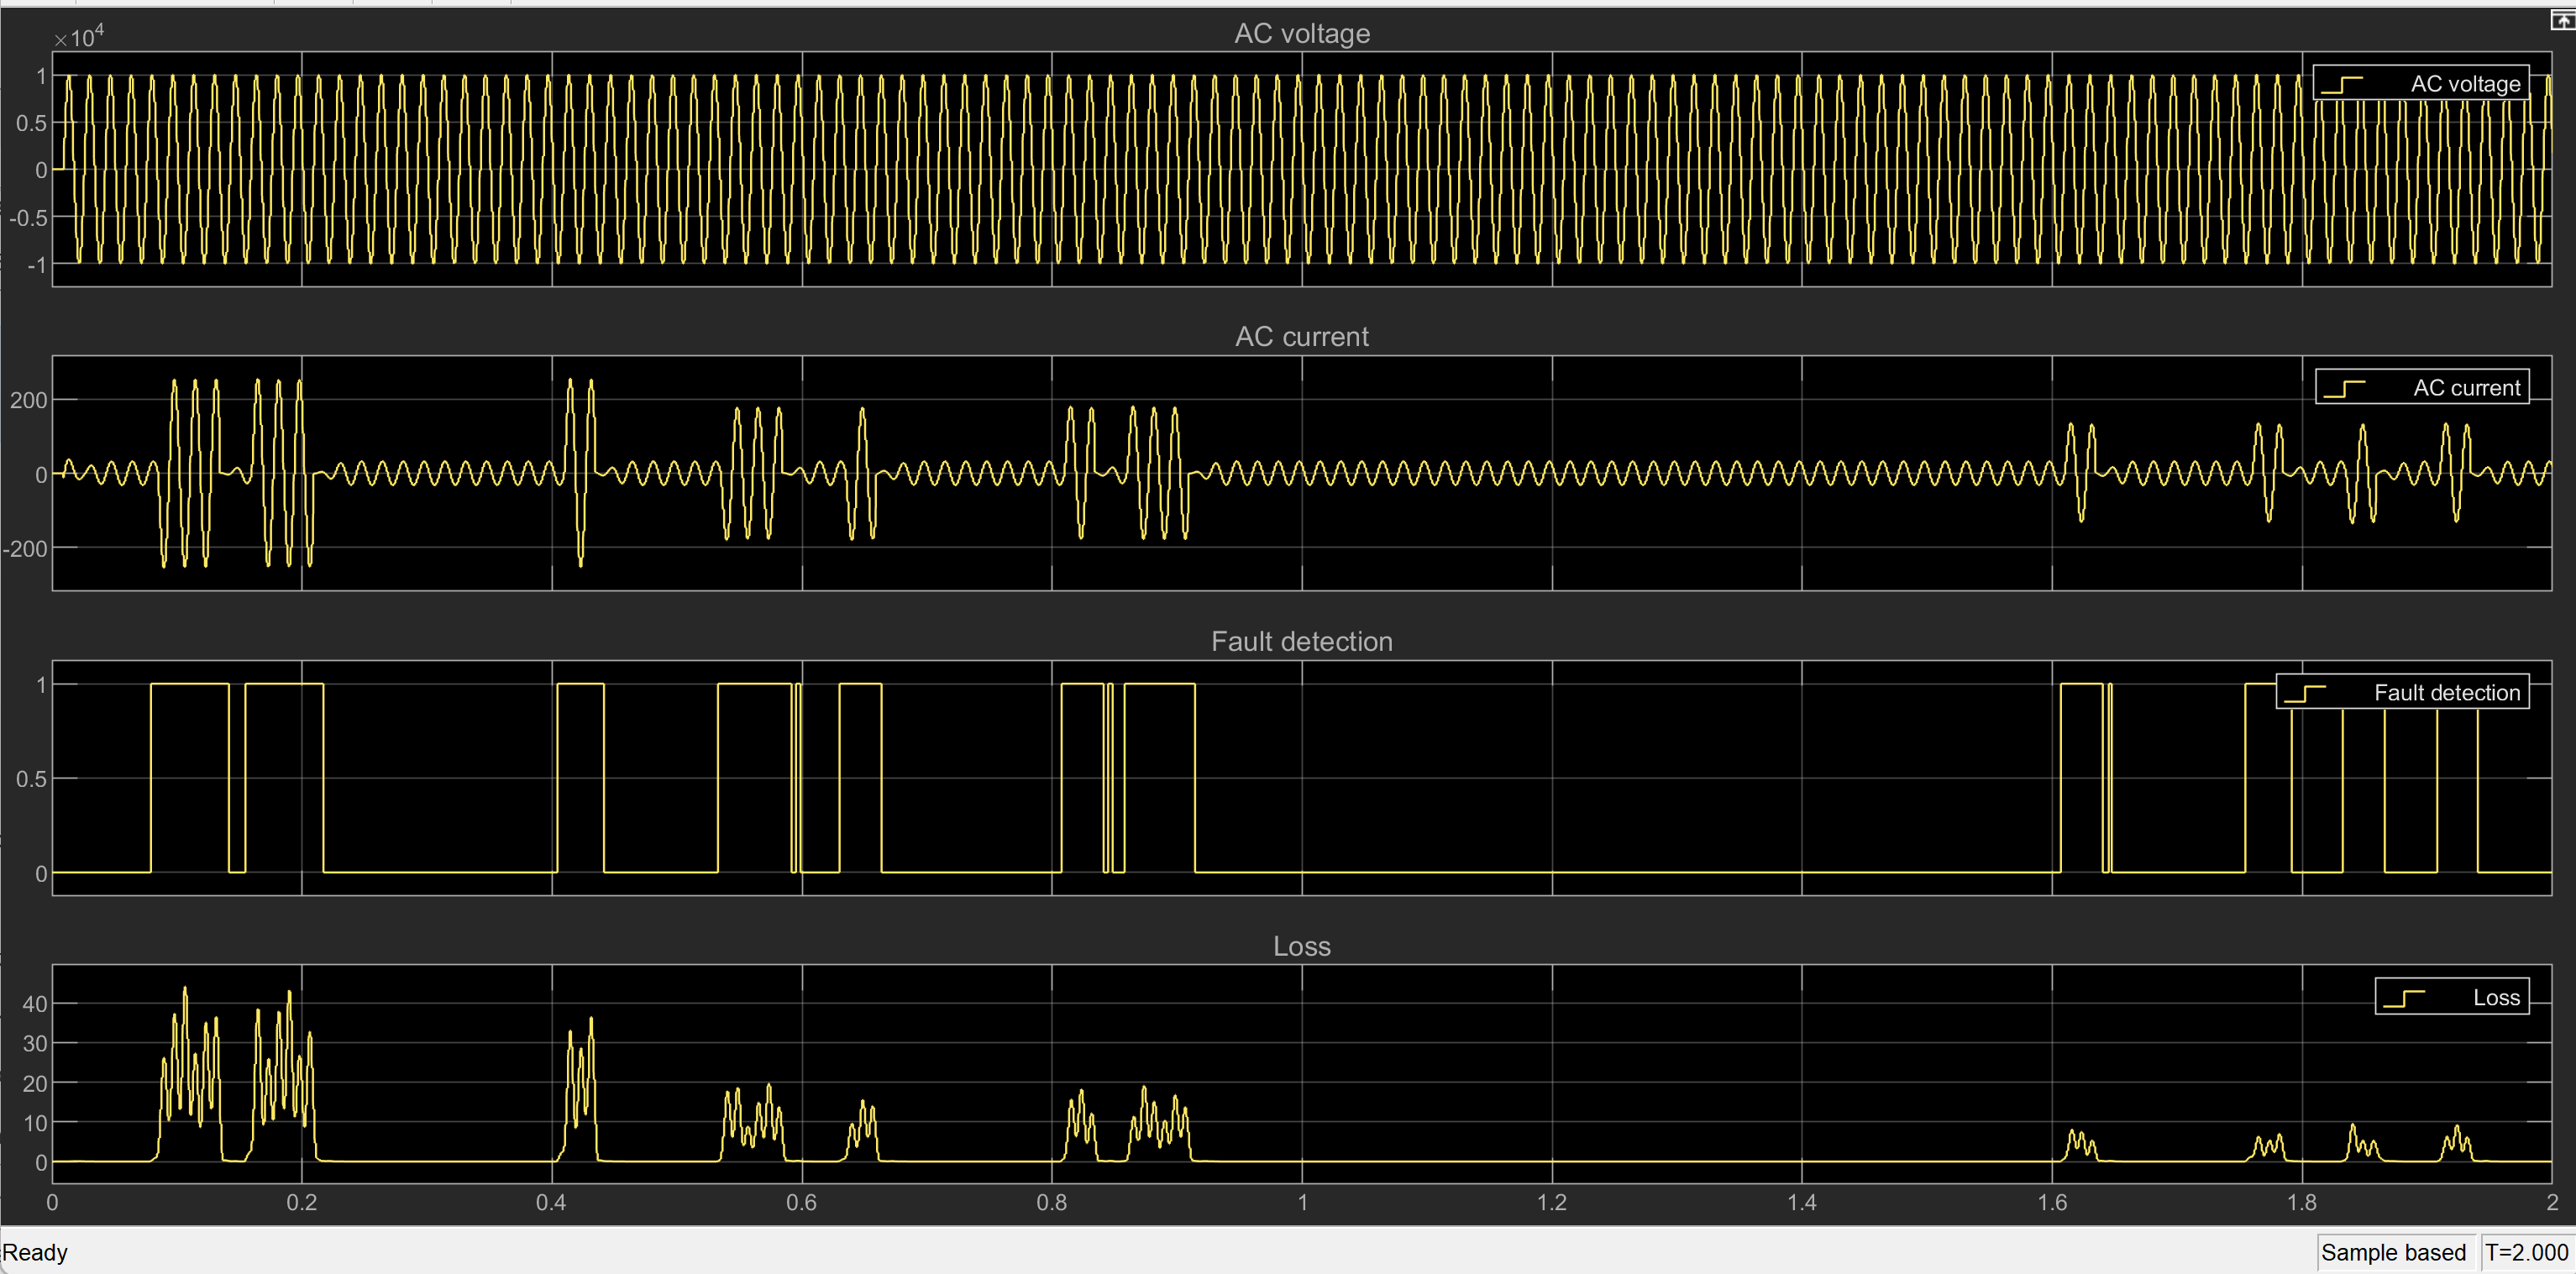

## Part 2 : Localize faults in three-phase transmission line

This section shows how to detect and localize faults in a three-phase power line. In addition to fault detection, it also identifies the specific phases affected by the fault.

### Create and train the LSTM autoencoder


VINormCell = {VInorm};  % Only one phase to localize

Create the LSTM autoencoder object using the `deepSignalAnomalyDetector` function. 

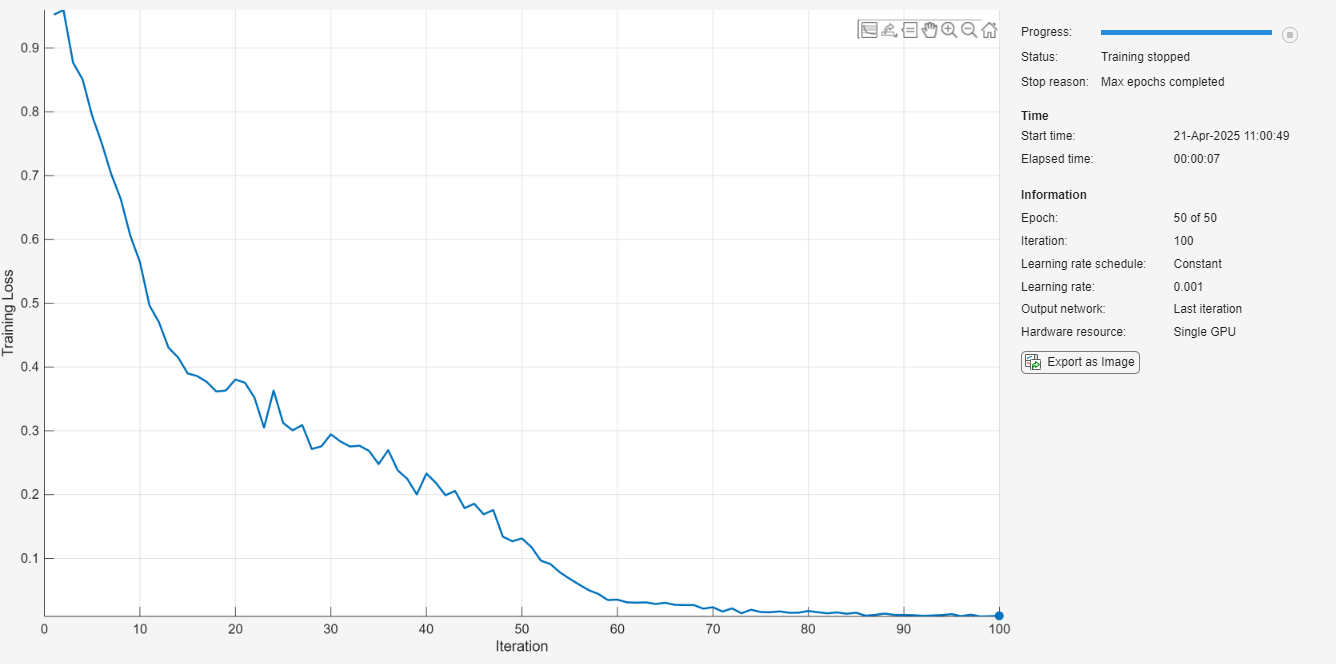

localizer = deepSignalAnomalyDetector(2,"lstm",EncoderHiddenUnits=32 ,...
    DecoderHiddenUnits=32, WindowLength=50,ThresholdMethod="max",ThresholdParameter=2);

options.MaxEpochs = 50;
% Train the detector
if trainNow
    trainDetector(localizer,VINormCell,options);
end

Save the trained network and detection parameters of the trained detector to a MAT-file.

if trainNow
    saveModel(localizer,"singlePhaseFaultLocalizer.mat");
end

### Fault detection and localization in Simulink

Open the Simulink model `FaultLocalizationModel`. 

close_system(detectionModel,0);
localizationModel = "FaultLocalizationModel";
open_system(localizationModel);

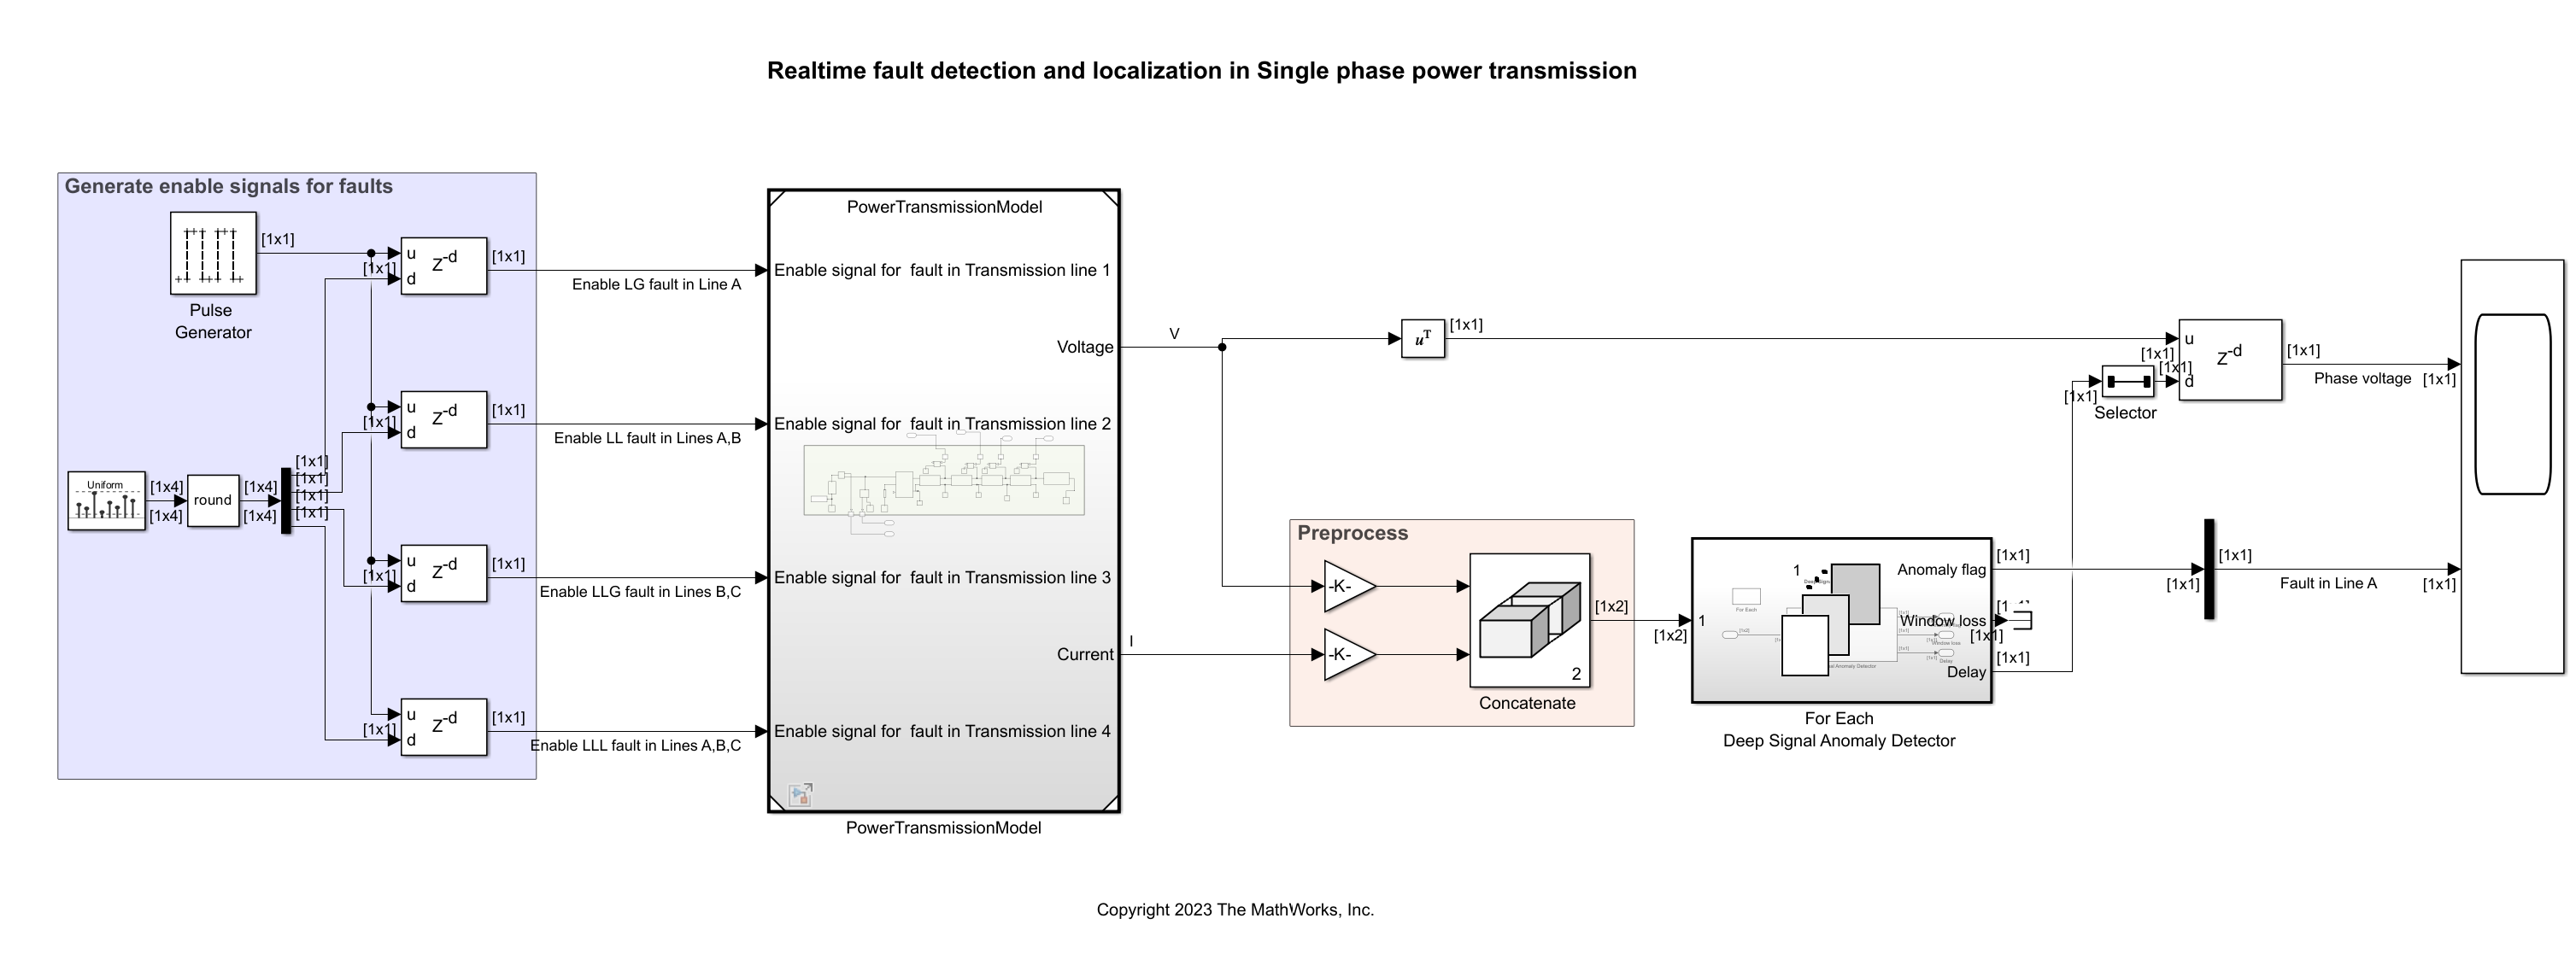

This model uses the same setup as the model `FaultDetectionModel `discussed in Part 1 to create a single-phase power transmission system and introduce short-circuit faults.

Place the Deep Signal Anomaly Detector block inside a For Each subsystem. Set the **Detector MAT-file path** parameter of the block to single`PhaseFaultLocalizer.mat`, which is the name of the MAT-file generated in the earlier section.

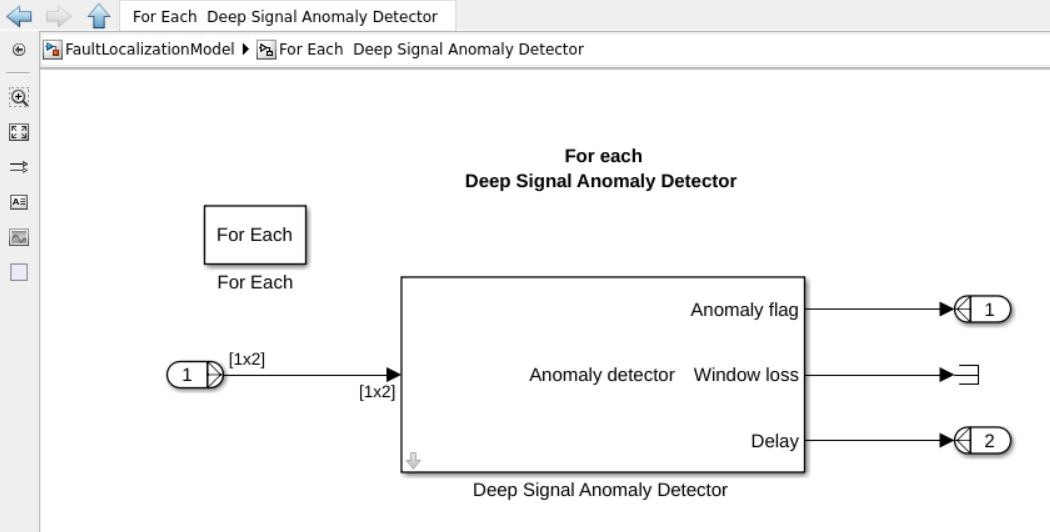

Set the **Partition Dimension** parameter of the[ For Each](docid:simulink_ref#bse8773) block to 1, corresponding to rows, since each row of the input contains the data corresponding to a different phase. 

Simulate the model.

sim(localizationModel);

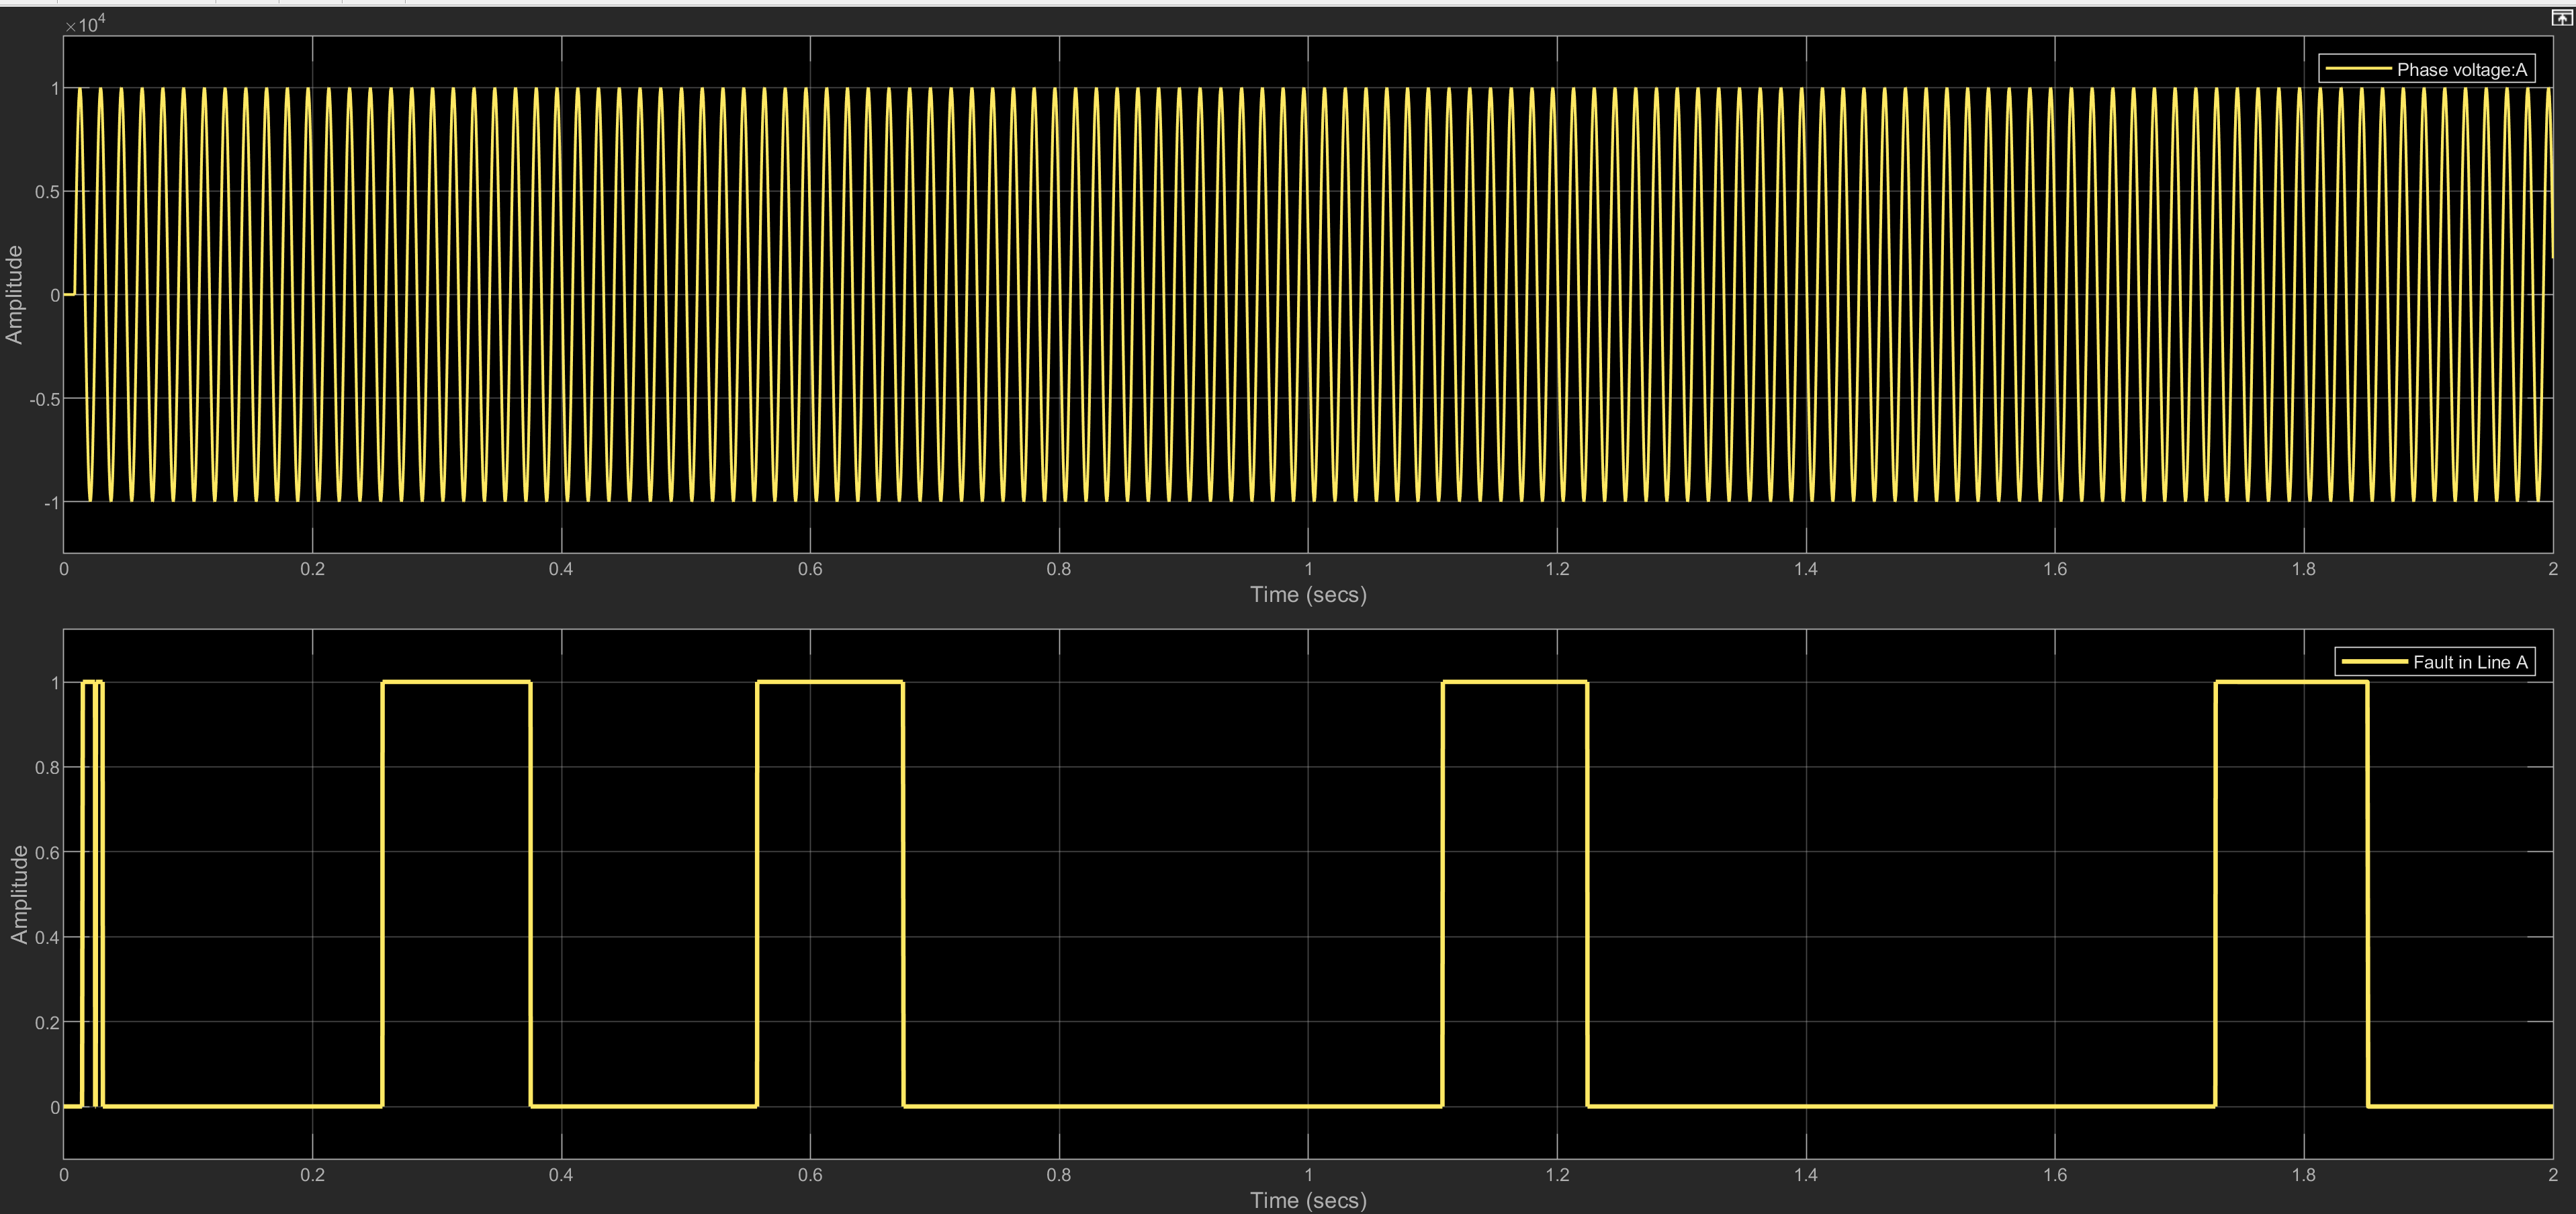

Observe the measured voltage in the single phases along with the fault detection on each of phases on the Time scope.

close_system(localizationModel,0);

## Summary

This example demonstrates the use of LSTM autoencoders to detect and localize short-circuit faults in single-phase power transmission systems. To detect the presence of a fault in the system without identifying the specific lines in which the fault occurs, train and employ a single anomaly detector by considering the voltage and current measurements across the phases as different features of the input data. To localize the fault, train the anomaly detector with two features (voltage, current), and employ a separate instance of the trained detector on each of the phases.

*Copyright 2023 The MathWorks, Inc.*